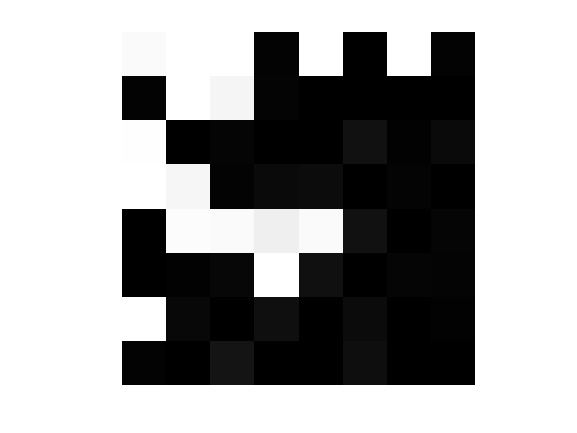

slika=imread('slika6.jpg');
slika= double(slika);
dctr = dct(slika);
idctr = idct(dctr);

dctmat = double(dctr);
idctmat = double(idctr);
K1 = zeros(8,8);
K1(:)=99;

K1(1:8,1:8) = [16,11,10,16,24,40,51,61;12,12,14,19,26,58,60,55;14,13,16,24,40,57,69,56;14,17,22,29,51,87,80,62;18,22,37,56,68,109,103,77;24,35,55,64,81,104,113,92;49,64,78,87,103,121,120,101;72,92,95,98,112,100,103,99];
K1dct = dctmat./K1;
K1dct = round(K1dct);
imwrite (K1dct, 'dctK1.jpg');
K1idct = idct(K1dct);
K1idct=uint8(K1dct);
imwrite (K1idct, 'idctK1.jpg');
figure();
imshow ('dctK1.jpg');

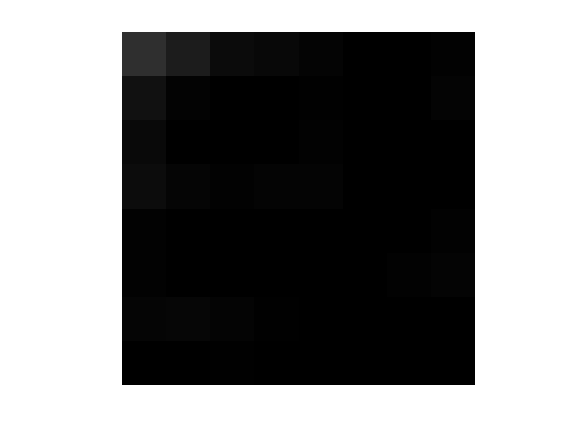

figure();
imshow ('idctK1.jpg');


K2 = 0.25.*K1

K2 =     4.0000    2.7500    2.5000    4.0000    6.0000   10.0000   12.7500   15.2500
    3.0000    3.0000    3.5000    4.7500    6.5000   14.5000   15.0000   13.7500
    3.5000    3.2500    4.0000    6.0000   10.0000   14.2500   17.2500   14.0000
    3.5000    4.2500    5.5000    7.2500   12.7500   21.7500   20.0000   15.5000
    4.5000    5.5000    9.2500   14.0000   17.0000   27.2500   25.7500   19.2500
    6.0000    8.7500   13.7500   16.0000   20.2500   26.0000   28.2500   23.0000
   12.2500   16.0000   19.5000   21.7500   25.7500   30.2500   30.0000   25.2500
   18.0000   23.0000   23.7500   24.5000   28.0000   25.0000   25.7500   24.7500


K2dct = dctmat./K2;
K2dct = round(K2dct)

K2dct =    271     8    99   -21     8     1     6     1
   -14    13    26   -18    -8     0     0     0
    60    -5   -17    -2    -3    -2    -2     0
    48    10     0     0     0    -3    -2     0
   -26    13     8     5     6    -3     0    -2
    -7    -6    -6     5     2     0     0    -2
    13    -1    -2     0    -2     0    -1    -2
    -5     2     2     2     2    -1     2    -2


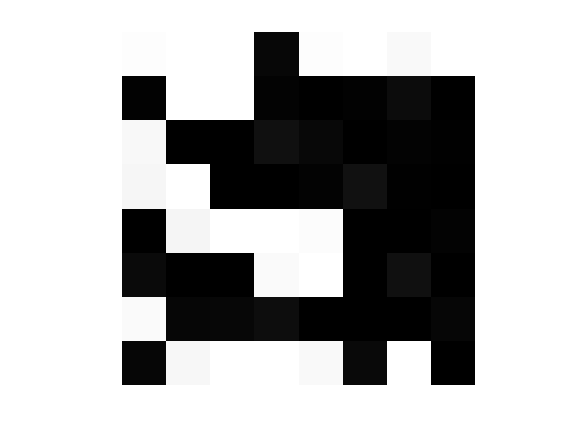

imwrite (K2dct, 'dctK2.jpg');
K2idct = uint8(idct(K2dct));
imwrite (K2idct, 'idctK2.jpg');
figure();
imshow ('dctK2.jpg');

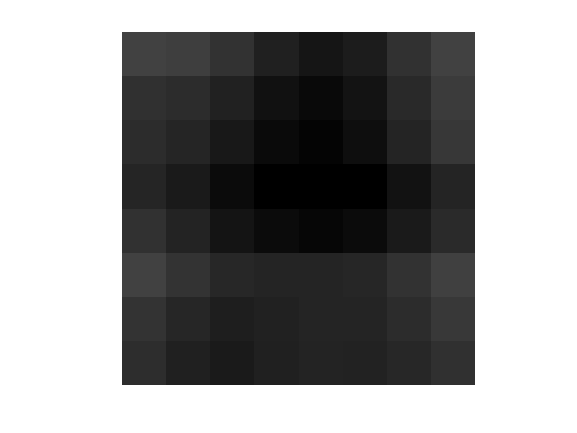

figure();
imshow ('idctK2.jpg');


K1_C = dctmat./K1;
K3 = 0.5.*K1

K3 =     8.0000    5.5000    5.0000    8.0000   12.0000   20.0000   25.5000   30.5000
    6.0000    6.0000    7.0000    9.5000   13.0000   29.0000   30.0000   27.5000
    7.0000    6.5000    8.0000   12.0000   20.0000   28.5000   34.5000   28.0000
    7.0000    8.5000   11.0000   14.5000   25.5000   43.5000   40.0000   31.0000
    9.0000   11.0000   18.5000   28.0000   34.0000   54.5000   51.5000   38.5000
   12.0000   17.5000   27.5000   32.0000   40.5000   52.0000   56.5000   46.0000
   24.5000   32.0000   39.0000   43.5000   51.5000   60.5000   60.0000   50.5000
   36.0000   46.0000   47.5000   49.0000   56.0000   50.0000   51.5000   49.5000


K3dct = dctmat./K3;
K5dct = round(K3dct)

K5dct =    135     4    50   -10     4     1     3     1
    -7     6    13    -9    -4     0     0     0
    30    -2    -8    -1    -2    -1    -1     0
    24     5     0     0     0    -2    -1     0
   -13     6     4     2     3    -2     0    -1
    -3    -3    -3     2     1     0     0    -1
     7    -1    -1     0    -1     0    -1    -1
    -2     1     1     1     1    -1     1    -1


imwrite (K5dct, 'dctK3.jpg');
K3idct = uint8(idct(K5dct));
imwrite (K3idct, 'idctK3.jpg');
figure();
imshow ('dctK3.jpg');

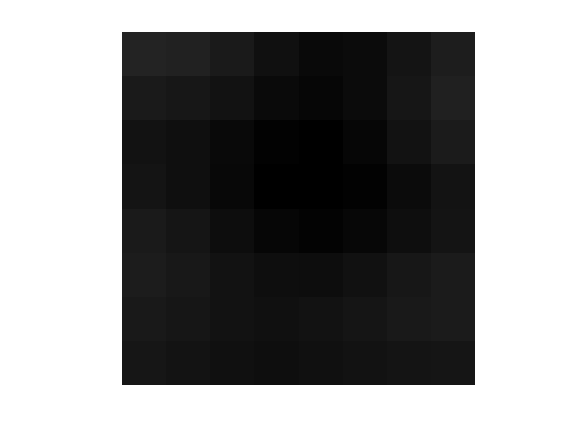

figure();
imshow ('idctK3.jpg');


K4 = 0.75.*K1

K4 =    12.0000    8.2500    7.5000   12.0000   18.0000   30.0000   38.2500   45.7500
    9.0000    9.0000   10.5000   14.2500   19.5000   43.5000   45.0000   41.2500
   10.5000    9.7500   12.0000   18.0000   30.0000   42.7500   51.7500   42.0000
   10.5000   12.7500   16.5000   21.7500   38.2500   65.2500   60.0000   46.5000
   13.5000   16.5000   27.7500   42.0000   51.0000   81.7500   77.2500   57.7500
   18.0000   26.2500   41.2500   48.0000   60.7500   78.0000   84.7500   69.0000
   36.7500   48.0000   58.5000   65.2500   77.2500   90.7500   90.0000   75.7500
   54.0000   69.0000   71.2500   73.5000   84.0000   75.0000   77.2500   74.2500


K4dct = dctmat./K4;
K4dct = round(K4dct)

K4dct =     90     3    33    -7     3     0     2     0
    -5     4     9    -6    -3     0     0     0
    20    -2    -6    -1    -1    -1    -1     0
    16     3     0     0     0    -1    -1     0
    -9     4     3     2     2    -1     0    -1
    -2    -2    -2     2     1     0     0    -1
     4     0    -1     0    -1     0     0    -1
    -2     1     1     1     1     0     1    -1


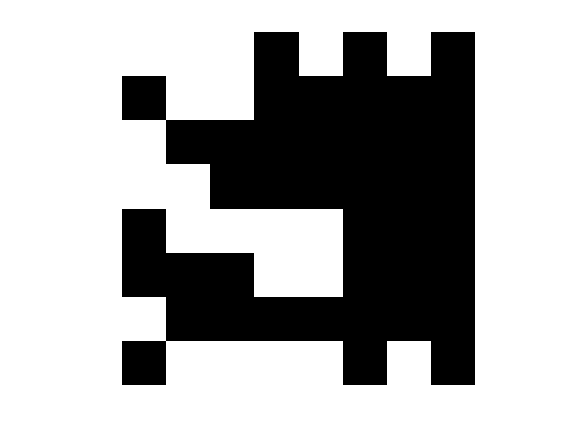

imwrite (K4dct, 'dctK4.bmp');
K4idct =uint8(idct(K4dct));
imwrite (K4idct, 'idctK4.bmp');
figure();
imshow ('dctK4.bmp');

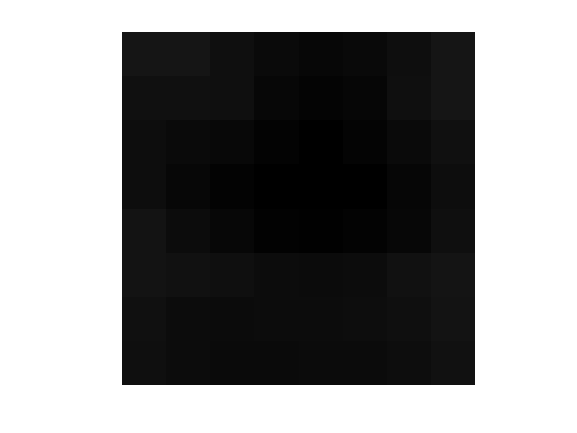

figure();
imshow ('idctK4.bmp');


K5 = 0.95.*K1

K5 =    15.2000   10.4500    9.5000   15.2000   22.8000   38.0000   48.4500   57.9500
   11.4000   11.4000   13.3000   18.0500   24.7000   55.1000   57.0000   52.2500
   13.3000   12.3500   15.2000   22.8000   38.0000   54.1500   65.5500   53.2000
   13.3000   16.1500   20.9000   27.5500   48.4500   82.6500   76.0000   58.9000
   17.1000   20.9000   35.1500   53.2000   64.6000  103.5500   97.8500   73.1500
   22.8000   33.2500   52.2500   60.8000   76.9500   98.8000  107.3500   87.4000
   46.5500   60.8000   74.1000   82.6500   97.8500  114.9500  114.0000   95.9500
   68.4000   87.4000   90.2500   93.1000  106.4000   95.0000   97.8500   94.0500


K5dct = dctmat./K5;
K5dct = round(K5dct)

K5dct =     71     2    26    -5     2     0     2     0
    -4     3     7    -5    -2     0     0     0
    16    -1    -4     0    -1     0     0     0
    13     3     0     0     0    -1     0     0
    -7     3     2     1     2    -1     0     0
    -2    -2    -2     1     0     0     0     0
     3     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0


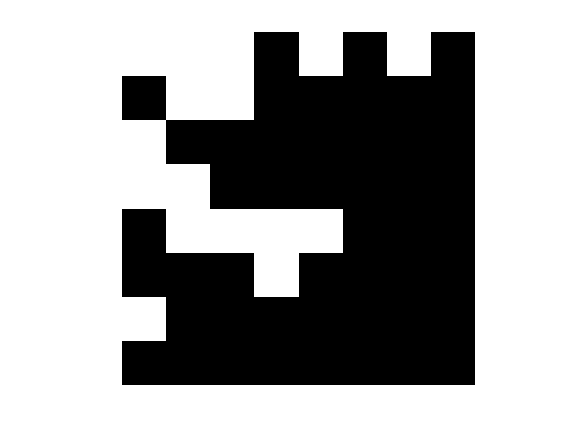

imwrite (K5dct, 'dctK5.bmp');
K5idct = uint8(idct(K5dct));
imwrite (K5idct, 'idctK5.bmp');
figure();
imshow ('dctK5.bmp');

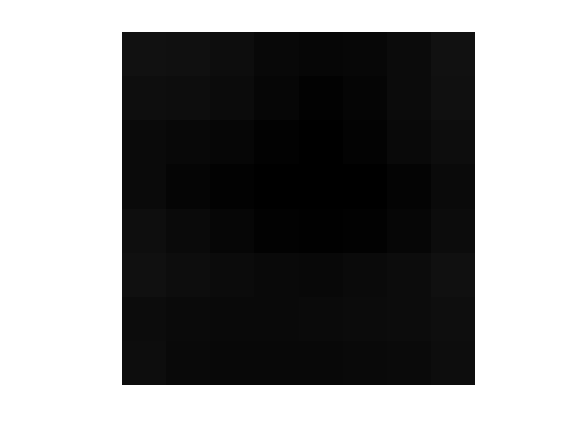

figure();
imshow ('idctK5.bmp');